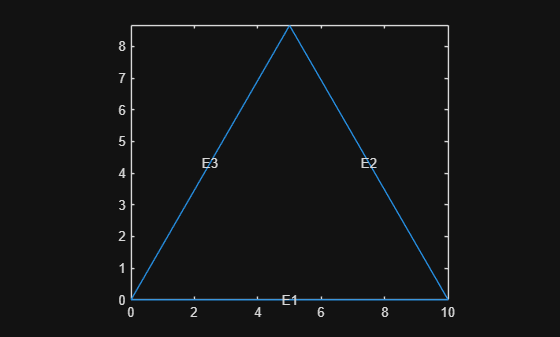

%% -------------------------------------------------------------
% Resolucion de la ecuacion del calor en un triangulo equilatero
%     de lado 10, con vertices en (0,0), (0,10) y (5√3,5).
%% -------------------------------------------------------------

clc
clear all
tic
% Crear el modelo PDE
model = createpde();

% Definir la geometria
L = 10;
% 2 = poligono, 3 = numero de vertices, vertice1, vertice2, vertice3
R1 = [2, 3,   0,   10,   5,    0,    0,    5*sqrt(3)]';
g  = decsg(R1); % decodifica la descripcion geometrica
geometryFromEdges(model, g);

% Visualizar la geometria y numerar las aristas
figure
pdegplot(model, "EdgeLabels", "on")
axis equal

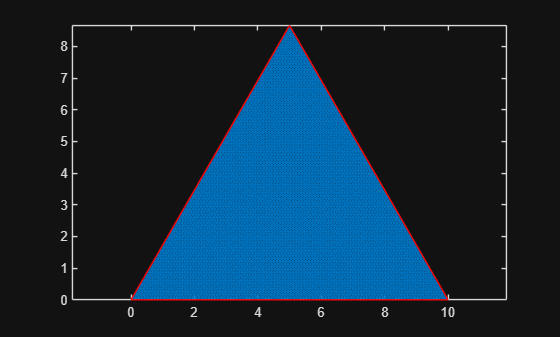


% Aplicar condicion de contorno Dirichlet homogenea (u = 0) en las 3 aristas
applyBoundaryCondition(model, "dirichlet", "Edge", [1, 2, 3], "u", 0);

% Generar malla triangular
generateMesh(model, "Hmax", 0.1);

% Visualizar la malla para comprobar densidad y cobertura
figure
pdemesh(model)
axis equal

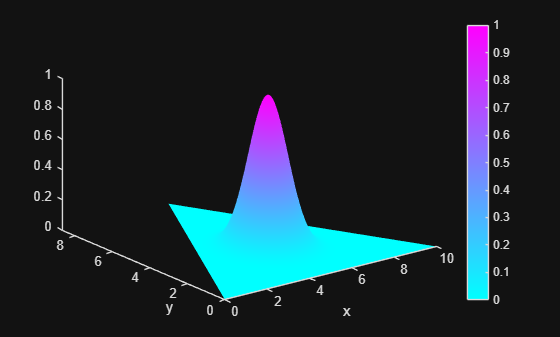

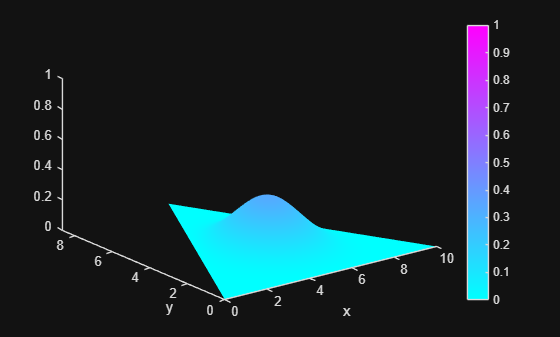

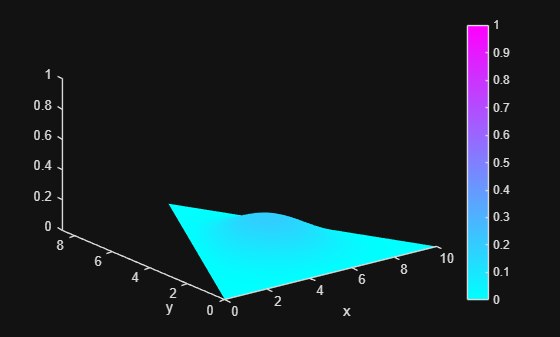


% Especificar coeficientes de la PDE para la ecuación del calor
%    La forma general que la toolbox acepta es
%      m ∂^2u/∂t^2 + d ∂u/∂t - ∇·(c ∇u) + a u = f.
specifyCoefficients(model, ...
    "m", 0, ...   % sin termino de segundo orden en t
    "d", 1, ...   % termino de primer orden en t
    "c", 1, ...   % difusividad unitaria
    "a", 0, ...   % sin termino en u
    "f", 0);      % sin fuente interna

% Fijar la condicion inicial, gaussiana centrada en (xc, yc)
xc = L / 2;
yc = L / 3;
setInitialConditions(model, @(location) exp(-((location.y - yc).^2 + (location.x - xc).^2)));

% Definir vector de tiempos para simular y resolver la PDE
tlist = 0 : 0.01 : 1;
result = solvepde(model, tlist); % dimension [NumeroDeNodos × length(tlist)]

% Definimos los tiempos a representar
tiempos_obj = [0, 0.5, 1];

% Para cada tiempo encontramos el indice en tlist de valor mas cercano
indices = zeros(size(tiempos_obj));
for k = 1:numel(tiempos_obj)
    [~, indices(k)] = min(abs(tlist - tiempos_obj(k)));
end

% Ahora generamos una figura independiente para cada uno de esos instantes
for k = 1:numel(indices)
    idx = indices(k);
    
    figure
    u_temp = result.NodalSolution(:, idx);
    pdeplot(model, "XYData", u_temp, "ZData", u_temp);
    
    title(sprintf("Temperatura en t = %.2f", tlist(idx)));
    xlabel("x"), ylabel("y")
    xlim([0 L])
    ylim([0 sqrt(3/4)*L])

    colorbar
    zlim([0 1]);      % Mantiene el rango vertical de u en [0,1]
    caxis([0 1]);     % Escala de colores en [0,1]
    view(3)           % Vista 3D fija
    
    pause(0.1)
end

toc

Elapsed time is 4.653536 seconds.



nodes = model.Mesh.Nodes;
nodes = nodes';
solutions = result.NodalSolution;
data = [nodes, solutions];
writematrix(data, 'heat_2D_results.csv');